# Simulation of the gaussian beam through an optical fiber

Every parameter in this program is in SI units.

## Parameters

Numerical parameters

res = 1e3; % Numerical resolution 

Physical parameters

l = 1000e-6; % Wavelength
Ns = 1.45; % Silica idex
Na = 1; % Air index (for later)

Laser parameters

On = 4e-1; % Numerical aperture
w0 = 1e-3; % Waist
M = sqrt(pi*w0^2*On/l); % Square root of the beam-quality factor
zr = w0/On; % Rayleigh distance

Fiber parameters

R = 60e-6; % Curvature radius
z0 = -10e-6 ; % Position of the interface
zmax = z0 + R; % Radius of the fiber

## Simulations

Inline function to compute the Complex beam parameter

q = @(z) z - z0 + 1i*zr;

Inline function to compute the Gaussian beam width

W = @(z) w0*sqrt(1+(z/zr)^2);

Matrix representation of the picture

P = []; 
                
x = linspace(-w0,w0,res); % Transverse coordonates
z = linspace(0,zmax,res); % Propagation coordinates

Q = NaN(size(z)); % matrix containing all the complex beam parameters value
Q(1,1) = feval(q,z(1,1)); % Initialization of the first value
passed = false; % Boolean checking that we only pass the interface once (Numerical simulation artefact)


for idx = 2:numel(z)
    zTemp = z(idx); % Retriveing value corresponding to the index (Parellization artefact)
    
    % Interface case
    if zTemp >= z0 && ~passed % <- Not passed
        % Air/Silica interface ABCD matrix
        A = 1;
        B = 0;
        C = (Na-Ns)/(R*Ns);
        D = Na/Ns;
        Mas = [A,B;
            C,D];
        % Computation of the simulated output complex beam parameter after the interface
        Q2 = Mas*[Q(idx-1);1];
        Q(1,idx) = Q2(1,1)/Q2(2,1); % Retrieving the first line and normalizing
        passed = true;
    else
        % Propagation matrix (air or silica)
        B = zTemp; % Position of the considered point (variable)
        C = 0;
        D = 1;
        Mp = [A,B;
            C,D];
        % Computation of the simulated output complex beam parameter
        Q2 = Mp*[Q(idx-1);1];
        Q(1,idx) = Q2(1,1)/Q2(2,1); % Retrieving the first line and normalizing
    end
    
    % Computation of the real radius
    % R = 1/(1/q2+1i*l*M^2/(pi*Ns*W^2));
    
    % Computation of the intensity on the zTemp-plane
    U = @(x,zTemp) 1/Q(1,idx)^(M^2/2)... <- For readability
        .*(exp(-(1i*pi*x.^2)/(l*Q(1,idx)))...
        .*polyval(hermitePoly(M^2),sqrt(2)*(M.*x)/(feval(W,zTemp))));
    I = abs(feval(U,x,zTemp).^2);
    P = [P;I];
end   

## Plotting

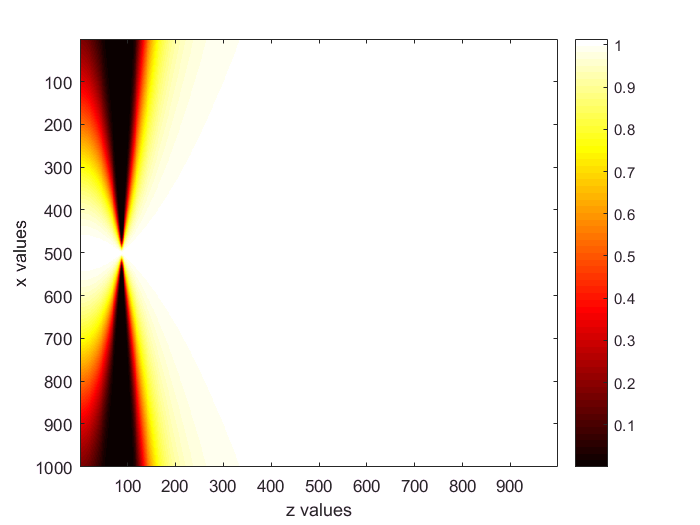

imagesc(P'); colormap(hot); colorbar;
ylabel('x values'); % yticks([0 z(1,res/2) z(1,res)]); yticklabels({'-2\omega_0','0','2\omega_0'})
xlabel('z values'); % xticks([0 z0 res]); xticklabels({'0','interface','center'});